test = 1:10000;
mu = 0;
sigma = 0.01;
pd = makedist('Normal','mu',mu,'sigma',sigma);
r = random(pd,size(test))

r =     0.0348    0.0015    0.0033    0.0041   -0.0061    0.0023   -0.0086    0.0010   -0.0077   -0.0145   -0.0049    0.0224    0.0160    0.0020   -0.0088   -0.0174   -0.0049   -0.0011   -0.0052    0.0058    0.0146    0.0056    0.0088    0.0037   -0.0151    0.0026    0.0036   -0.0168    0.0007    0.0092   -0.0219   -0.0024    0.0006    0.0071    0.0190    0.0009   -0.0004    0.0005    0.0098   -0.0236   -0.0078    0.0114    0.0043    0.0052    0.0091   -0.0008   -0.0221    0.0208   -0.0054   -0.0120


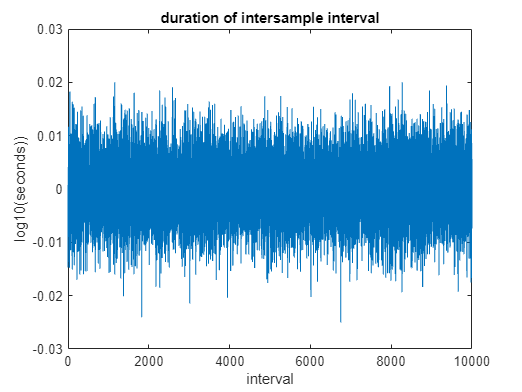

test = test + r;

% Calculate intersample interval
dt = diff(test);
figure(); plot(log10(dt))
title("duration of intersample interval")
ylabel("log10(seconds))")
xlabel("interval")


%compute the Allan Variance of the Intersample Interval Duration
dt_tau = 1:length(dt)/2;
dt_avar=allanvar(dt,dt_tau); % tau channel

%Compute the slope of the clock Allan Variance over Tau
idx = dt_tau >= 1 & dt_tau <= 1000;   % sample region
% linear fit in log10-log10 space; 
p = polyfit(log10(dt_tau(idx)), log10(dt_avar(idx)), 1);
disp("LogLog Slope:" + p(1)) % p(1) = slope;

LogLog Slope:-2.0008


disp("LogLog Intercept:" + p(2)) % p(2) = intercept;

LogLog Intercept:-3.535


disp("AVAR(\tau)=" + p(2) +"\tau^"+ p(1))

AVAR(\tau)=-3.535\tau^-2.0008


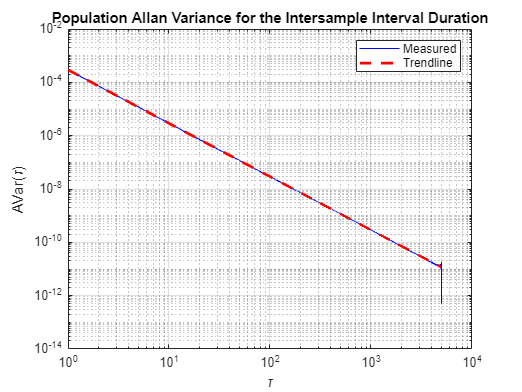


yfit = 10.^(p(1)*log10(dt_tau) + p(2)); %create the best fit line

figure();
loglog(dt_tau, dt_avar, 'b'); hold on;grid on;
loglog(dt_tau, yfit, 'r--', 'LineWidth', 2);
title("Population Allan Variance for the Intersample Interval Duration");
xlabel('\tau'); ylabel('AVar(\tau)');
legend("Measured", "Trendline");
hold off


predictionTaus = 10.^[0;1;2;3;4;5;6];
predictedJitter = 10.^(p(1)*log10(predictionTaus) + p(2));
table(predictionTaus,predictedJitter)

ans = 7×2 table
    predictionTaus    predictedJitter
    ______________    _______________

            1           0.00029174   
           10           2.9124e-06   
          100           2.9073e-08   
         1000           2.9023e-10   
        10000           2.8973e-12   
        1e+05           2.8923e-14   
        1e+06           2.8873e-16   


%Rolling ALLAN on the data
maxtau=30;minpartitions = 4;
maxpts = maxtau*minpartitions; %seconds of window
%tau = [1,2,4,5,8,10,15,20,%intervals on the binary then to every 5 seconds
tau=[1:maxtau];%unique(round(2.^(0:0.01:log2(maxpts/2))));
seconds=height(sensorData)-maxpts;
avar = zeros([length(tau) width(sensorData) seconds]);
slices = 1:seconds;

for i = slices
    avar(:,:,i)=allanvar(sensorData(i:i+maxpts,:),tau);
end
size(avar)%avar(tau,channel,slices)
toc

x   = TimeTemp{:,"robustAvg"};
N   = length(x);
Htau = 1:floor(N/3);          % in samples; map to seconds if you want

Hvar = zeros(size(Htau));

for i = 1:length(Htau)
    m = Htau(i);
    idxMax = N - 2*m;
    d2 = x(1+m:idxMax+m) - 2*x(1:idxMax) + x(1+2*m:idxMax+2*m);
    Hvar(i) = mean(d2.^2) / 6;
end

loglog(Htau, Hvar); grid on;
xlabel('\tau (samples)'); ylabel('\sigma_H^2(\tau)');
title('3-point Hadamard variance of robustAvg');
toc


